# Logistic Regression and Support Vector Machines

## 1. Logistic Regression

This is an example of a binary classification using Logistic Regresion in MATLAB, including data split, training, evaluation and visualisation of the decision boundary. The example data sets provided with this code (exdata1.mat, exdata2.mat and exdata3.mat) all contain two features. 

### 1.1 Review of Logistic regression

#### 1.1.1 Cross entropy cost function

The hypothesis function is given by 


$$h\left(x\right)=\sigma \left(\theta \cdot x\right)=\frac{1}{1+e^{-\theta \cdot x} }$$


The cost function used in logistic regresion is given by:


$$J(\theta) =-\frac{1}{m}\sum_{i=1}^m{\left[
y^{(i)} \ln(\sigma(x^{(i)}))+(1-y^{(i)}) \ln(1-\sigma(x^{(i)}))\right]+\lambda\sum_{j=1}^n{\theta_j^2},$$


#### 1.1.2 Gradient

The gradient of such cost function is given by:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( \sigma(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( \sigma(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+2 \lambda \theta_j\qquad \mathrm{for}\;j\geq1,$$


#### 1.1.3 Feature mapping

In many cases, the decision boundary between clasess will be nonlinear

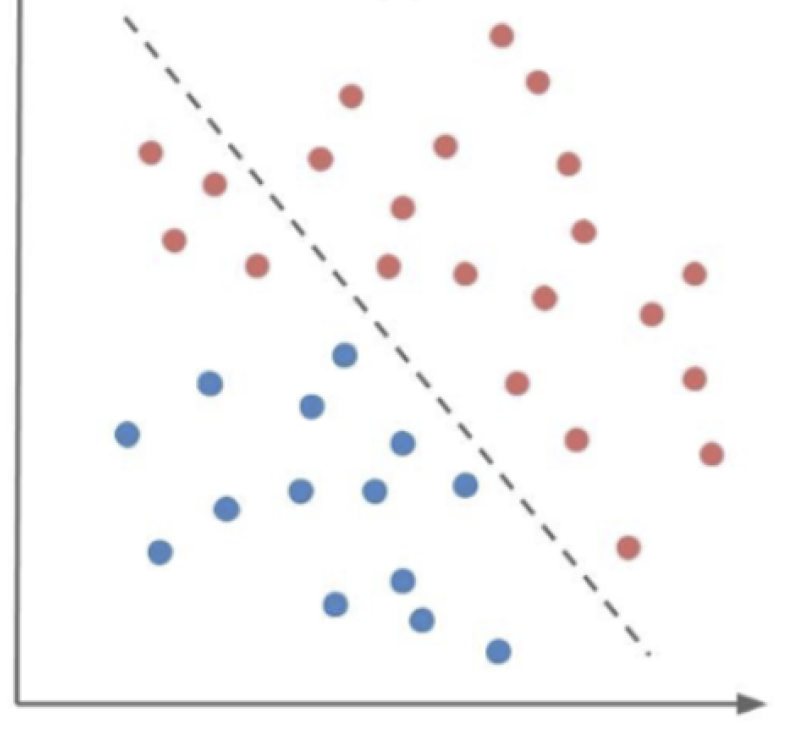                     

Linear decision boundary

             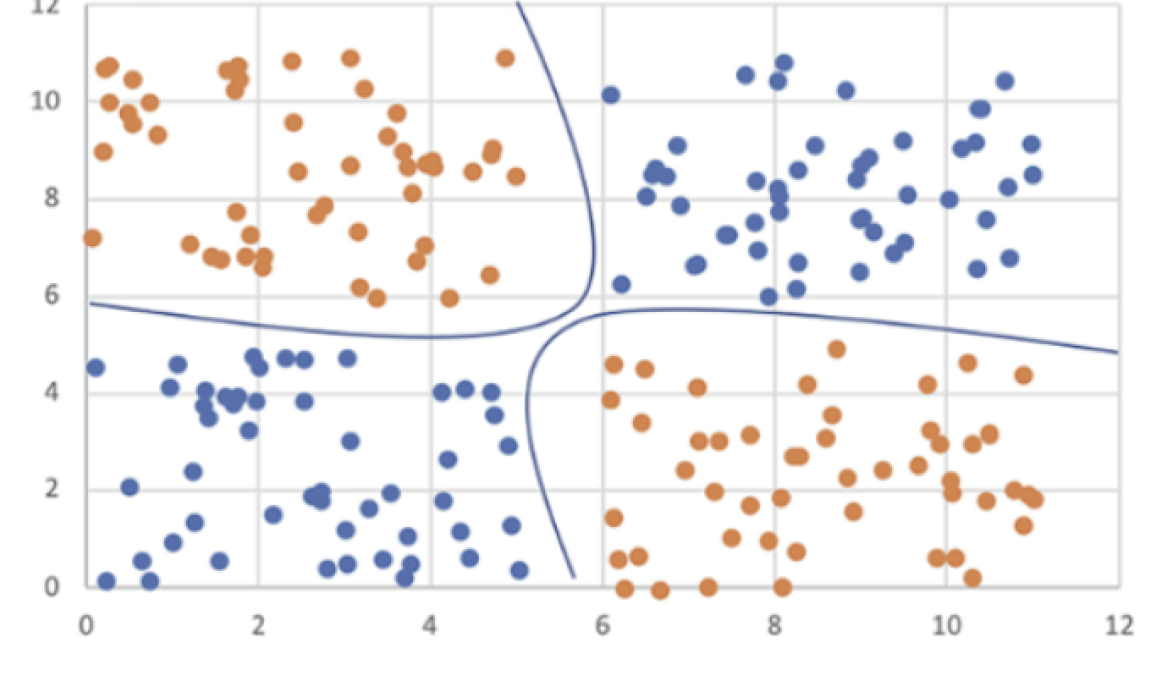 

Nonlinear decision boundary

A trick to consider those nonlinear boundaries is to use the available data to provide new nonlinear features!


$$\mathrm{Feature\_mapping}(x) = \left[ x_1, \ x_2, \ x_1^2, \ x_1x_2, \ x_2^2, \ x_1^3, \cdots, \  x_1x_2^5, \ x_2^6 \right]$$


### 1.2 Data

The data is saved in a matrix of features `X` and a separate labels vector `y`. In order to be able to evaluate the model after training, we first need to split it into training and testing set. This is done using the `cvpartition` function from the Statistics & ML Toolbox which selects a random sample of specified size ('`HoldOut`') from the dataset.

dataset = 'exdata2.mat';
load(dataset);
% Combine data into one matrix so that assigned labels are kept with features during random selection
Data = [X, y]; 
% Reserve 20% of data for testing 
cv = cvpartition(size(Data,1),'HoldOut',0.2);
% Training data
X = Data(cv.training,1:2); 
y = Data(cv.training,3);
% Test data
X_test = Data(cv.test,1:2)

X_test =     0.0933    0.6499
    0.1555    0.7844
    0.8191    0.8794
    0.7661    0.8999
    0.8145    0.8326
    0.8145    0.8852
    0.5634    0.9218
    0.4942    0.8999
    0.4505    0.8999
    0.3514    0.9349


y_test = Data(cv.test,3)

y_test =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


Next we perform feature mapping

Feature_map = true;
if Feature_map
    X = Feature_mapping(X(:,1), X(:,2));
    X_test = Feature_mapping(X_test(:,1), X_test(:,2));
end

Remember to add the vector of ones in the features matrix $X$, due to the bias term $\theta_0$.

% Resize X by adding the bias term theta0
X = [ones(size(X,1),1),X];
X_test = [ones(size(X_test,1),1),X_test];

Data visualization

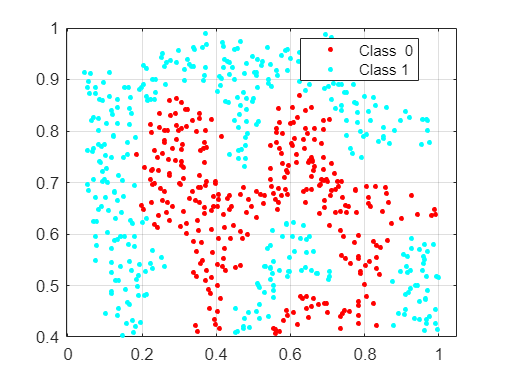

figure
hold on
gscatter(X(:,2),X(:,3),y) 
legend('Class  0', 'Class 1')
box on
grid on

### 1.3 Model and training

We are going to use matlab inbuilt gradient descent function `fminunc. `For this function we need to provide the cost function $J$ and, if known, the gradient. We use this to find the optimal value of parameters $\theta$ that classify our data. 

% Initialize fitting parameters
theta_init = zeros(size(X, 2), 1);
lambda = 0.001;
% Set Options
options = optimoptions(@fminunc);
options.Algorithm = 'Quasi-Newton';
options.GradObj =  'on';
options.MaxIter =  1000;
% Optimize
[theta, J, exit_flag] = fminunc(@(th)(CostFun_and_Grad(th, X, y, lambda)), theta_init, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


### 1.4 Evaluation

Once the model is trained, we can calculate its accuracy by making predictions on the reserved test data and calculating how many datapoints were correctly classified.

% Begin by setting all the predictions to label 0
label = zeros(size(X_test,1),1);
% Classify predictions above a specific threshold with label 1:
threshold = 0.5;
label(sigmoid(X_test*theta) >= threshold) = 1;

% Metrics for classification
TP = sum(and(label,y_test));                % True positives
FP = sum(and(label,not(y_test)));           % False positives
TN = sum(and(not(label),not(y_test)));      % True negatives
FN = sum(and(not(label),y_test));           % False negatives

accuracy  = (TP + TN)/(TP + TN + FP + FN)

accuracy = 0.7384

precision = TP/(TP + FP)

precision = 0.7667

recall    = TP/(TP + FN)

recall = 0.7419

F1score   = (2*precision*recall)/(precision + recall)

F1score = 0.7541

#### 1.4.1 Visualise decision boundary

Since our data here has only two features, we can also visualize the model by plotting the decision boundary

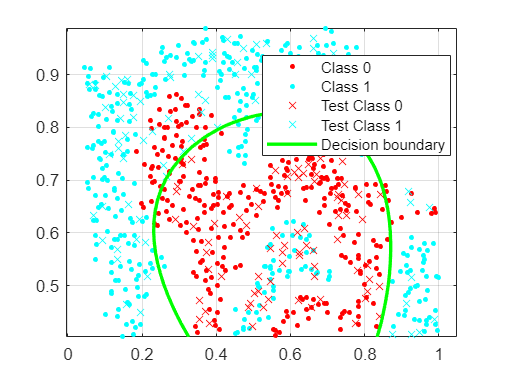

% Compute the scores over a grid
d = 0.02; % Step size of the grid
x1 = min(X(:,2)):d:max(X(:,2));
x2 = min(X(:,3)):d:max(X(:,3));
[x1Grid, x2Grid] = meshgrid(x1,x2);
% The grid
if Feature_map
    X_Grid = Feature_mapping(x1Grid(:), x2Grid(:));
else
    X_Grid = [x1Grid(:),x2Grid(:)];        
end
X_Grid = [ones(numel(x1Grid),1),X_Grid];
scores = sigmoid(X_Grid*theta); % The scores

figure
hold on
% Plots data
gscatter(X(:,2),X(:,3),y) 
gscatter(X_test(:,2),X_test(:,3),label,[],'x') 
% Plot decision boundary:
contour(x1Grid,x2Grid,reshape(scores,size(x1Grid)),[threshold threshold],'g', 'LineWidth',2);
legend('Class 0','Class 1','Test Class 0','Test Class 1','Decision boundary')
box on 
grid on
hold off

## 2. Support Vector Machines

This is an example of a binary classification SVM in MATLAB, including data split, training, evaluation and visualisation of the decision boundary. The example data sets provided with this code (exdata1.mat, exdata2.mat and exdata3.mat) all contain two features.

### 2.1 Review of SVM model parameters:

#### 2.1.1 Regularization parameter "C" (Box contraints)

The optimization with regularization using soft margins is given by:


$$\min \;\frac{1}{2}\left|\right|\mathit{\mathbf{w}}\left|{\left|\right.}^2 \;+C\;\sum_i^m \xi_i \right.$$



$$\begin{array}{l}
\textrm{subject}\;\textrm{to}\\
y_i \left(\mathit{\mathbf{w}}\cdot \mathit{\mathbf{x}}{\;}^{\left(i\right)} +b\right)\ge 1-\xi_i ,\\
\xi_i \ge 0
\end{array}$$


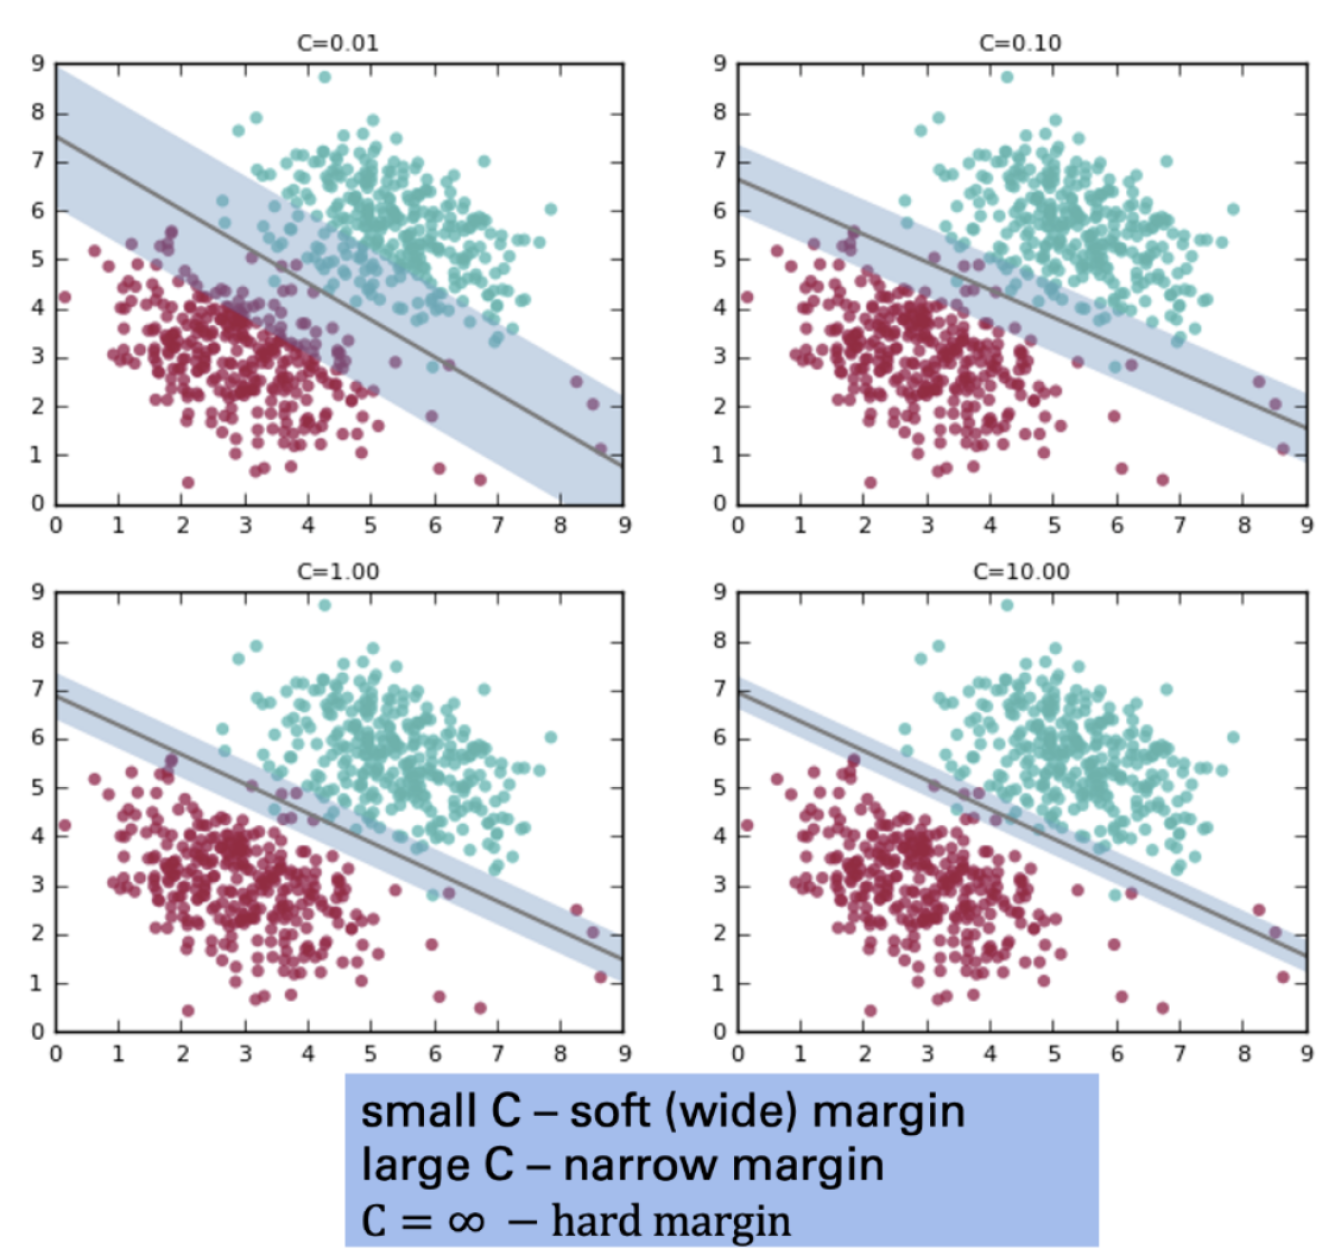

#### 2.1.2 The Kernel trick

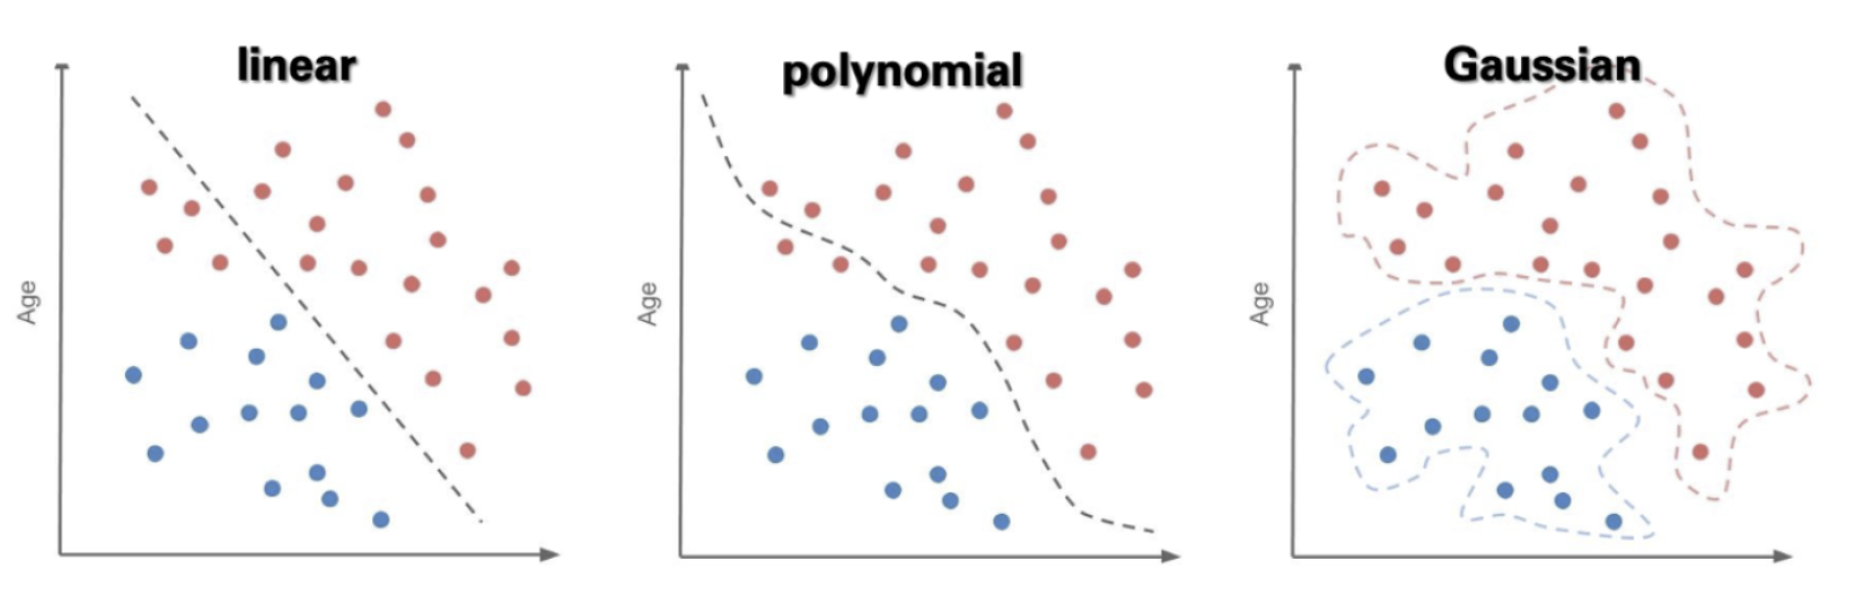

### 2.2 Data

The data is saved in a matrix of features `X` and a separate labels vector `y`. In order to be able to evaluate the model after training, we first need to split it into training and testing set. This is done using the `cvpartition` function from the Statistics & ML Toolbox which selects a random sample of specified size ('`HoldOut`') from the dataset.

dataset = 'exdata2.mat';
load(dataset);
% Combine data into one matrix so that assigned labels are kept with features during random selection
Data = [X, y]; 
% Reserve 20% of data for testing 
cv = cvpartition(size(Data,1),'HoldOut',0.2);
% Training data
X = Data(cv.training,1:2); 
y = Data(cv.training,3);
% Test data
X_test = Data(cv.test,1:2)

X_test =     0.0933    0.6499
    0.8099    0.8370
    0.7730    0.8545
    0.7661    0.8999
    0.7615    0.7654
    0.5104    0.9379
    0.2339    0.8618
    0.1601    0.7770
    0.1233    0.7917
    0.4136    0.9013


y_test = Data(cv.test,3)

y_test =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


Data visualization

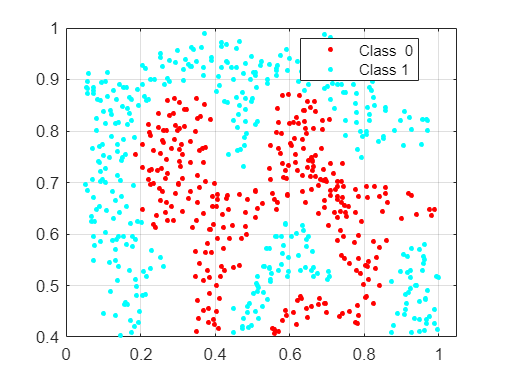

figure
hold on
gscatter(X(:,1),X(:,2),y) 
legend('Class  0', 'Class 1')
box on
grid on

### 2.3 Model and training

Since this data does not require any further cleaning or pre-processing, the next step is to define and train a model. In this case we define the model within the training function (`fitcsvm`). 

The function takes:

- a matrix of features `X` 

- a vector of labels `y` 

- type of kernel function (choose from `linear`, `gaussian`, `rbf`, `polynomial` or self-defined function)

- prompt to standardize (scale) features before training

- regularization parameter `BoxConstraint`

- amount of diagnostic information output during training: `Verbose` (0-none, 1-moderate, 2-abundant)

The function returns a trained model saved in a variable `SVMModel`.

All adjustable parameters can be found in the [documentation](https://uk.mathworks.com/help/stats/fitcsvm.html#bt9w6j6-3).

SVMModel = fitcsvm(X,y,...
    'KernelFunction','polynomial',...
    'PolynomialOrder',8,... % add only when polynomial kernel selected
    'Standardize',true, ...
    'BoxConstraint',1,...
    'Verbose', 0);

%SVMModel = fitcsvm(X,y,...
%    'KernelFunction','gaussian',...
%    'Standardize',true,...
%    'BoxConstraint',10,...
%    'Verbose',0);

The trained model contains all support vectors in `SVMModel.SupportVectors` (with coordinates after standardization) and a logic matrix `SVMModel.IsSupportVector `which can be used to plot support vectors without scaling.

You can also access Lagrangian multipliers of the model as `SVMModel.Alpha()` and weights of the hyperplanne as `SVMModel.Beta `(only with linear kernel) and the bias term ($\left.\theta_0 \right)$ as `SVMModel.Bias`.

### 2.4 Evaluation

Once the model is trained, we can calculate its accuracy by making predictions on the reserved test data and calculating how many datapoints were correctly classified.

% Return labels and probabilities of prediction
[label,~] = predict(SVMModel,X_test); 
% Metrics for classification
TP = sum(and(label,y_test));                % True positives
FP = sum(and(label,not(y_test)));           % False positives
TN = sum(and(not(label),not(y_test)));      % True negatives
FN = sum(and(not(label),y_test));           % False negatives

accuracy  = (TP + TN)/(TP + TN + FP + FN)

accuracy = 0.9593

precision = TP/(TP + FP)

precision = 0.9663

recall    = TP/(TP + FN)

recall = 0.9556

F1score   = (2*precision*recall)/(precision + recall)

F1score = 0.9609

#### 2.4.1 Visualise decision boundary

Since our data here has only two features, we can also visualize the model by plotting all support vectors and the decision boundary (contour plot of prediciton scores made on a mesh grid).

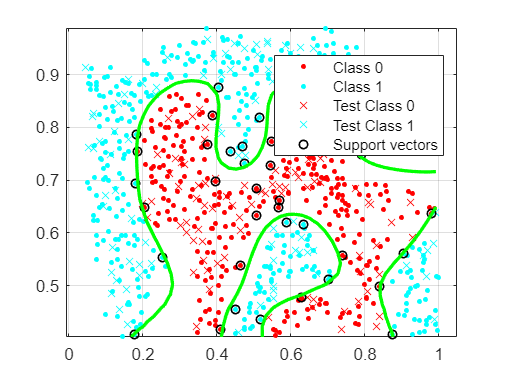

% Compute the scores over a grid
d = 0.02; % Step size of the grid
x1 = min(X(:,1)):d:max(X(:,1));
x2 = min(X(:,2)):d:max(X(:,2));
[x1Grid, x2Grid] = meshgrid(x1,x2);
xGrid = [x1Grid(:),x2Grid(:)];        % The grid
[~,scores] = predict(SVMModel,xGrid); % The scores

% Plot model with data and support vectors
sv = SVMModel.SupportVectors;
figure
hold on
% Plots data
gscatter(X(:,1),X(:,2),y) 
gscatter(X_test(:,1),X_test(:,2),label,[],'x') 
% Plot Support Vectors
plot(X(SVMModel.IsSupportVector,1),X(SVMModel.IsSupportVector,2),'ko','MarkerSize',5,'LineWidth',1);
% Plot decision boundary
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'g', 'LineWidth',2);
legend('Class 0','Class 1','Test Class 0','Test Class 1','Support vectors')
hold off
box on
grid on

*AERO70026\97081, Imperial College London, 2022*